# Testing MR

## 3D

input_img = new_run.rawImages;

% get dims 
Nround = size(input_img, 5);
Nchannel = size(input_img, 4);

% setup structure element
ms = offsetstrel('ball', 6, 3);
se = strel('sphere',2);

fprintf("====Morphological Reconstruction====\n");
for r=1:Nround 
    tic
    fprintf(sprintf("Processing Round %d...", r));
    
    for c=1:Nchannel
        curr_channel = input_img(:,:,:,c,r);
        marker = imerode(curr_channel, ms);
        obr = imreconstruct(marker, curr_channel);
        curr_out = curr_channel - obr;
        mask = imbinarize(curr_out,0.06);
        %curr_out(~mask) = 0;
        
        bw = imopen(mask, se);
        curr_out(~bw) = 0;
        
        curr_out = imsubtract(imadd(curr_out, imtophat(curr_out, ms)), imbothat(curr_out, ms));
        
        input_img(:,:,:,c,r) = uint8(curr_out);
    end
    fprintf(sprintf('[time = %.2f s]\n', toc));
end
    
img_show_3d = max(input_img(:,:,:,1,1), [], 3);
imshow(img_show_3d)


## 2D

input_img = new_run.rawImages;

% get dims 
Nround = size(input_img, 4);
Nchannel = size(input_img, 4);
Nslice = size(input_img, 3);

% setup structure element
se = strel('disk',6);
se_3 = strel('sphere',3);

fprintf("====Morphological Reconstruction====\n");

====Morphological Reconstruction====


Processing Round 1...

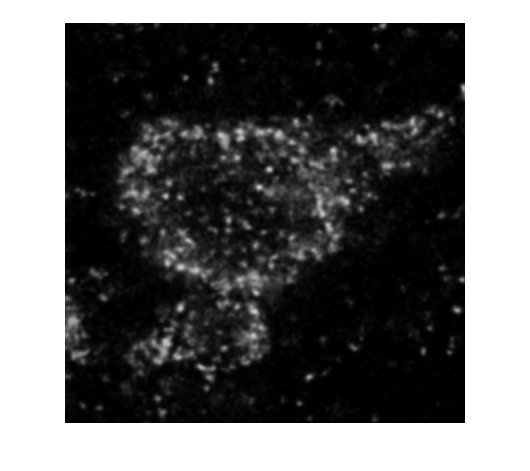

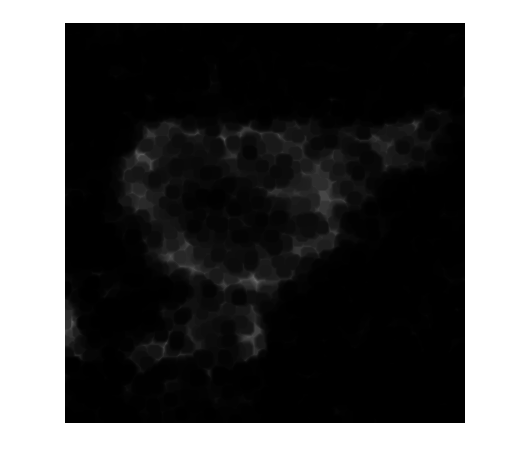

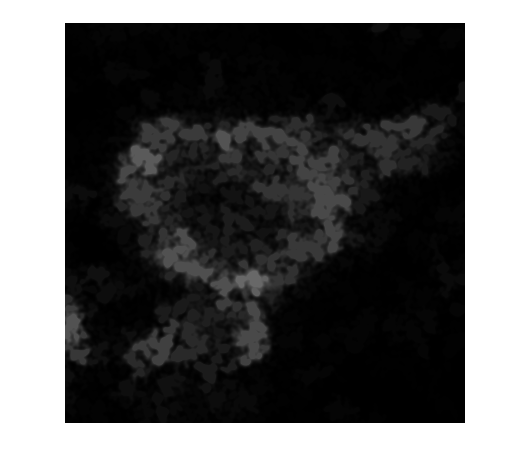

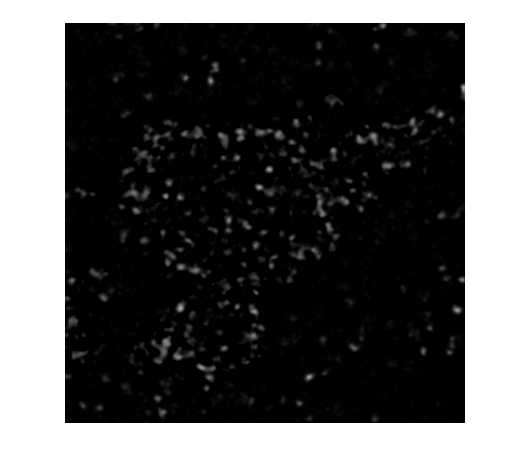

[time = 0.44 s]


for r=1:1
    tic
    fprintf(sprintf("Processing Round %d...", r));
    
    for c=1:1
        curr_channel = input_img(:,:,:,c,r);
        old = curr_channel;
        for z=1:1
            curr_slice = curr_channel(:,:,z);
            figure
            imshow(curr_slice)
            marker = imerode(curr_slice, se);
            figure
            imshow(marker)
            obr = imreconstruct(marker, curr_slice);
            figure
            imshow(obr)
            curr_out = curr_slice - obr;
            figure
            imshow(curr_out)
%             mask = imbinarize(curr_out,0.06);
%             mask = curr_out > 80;
%             curr_out(~mask) = 0;
%             
%             bw = imopen(mask, se_2);
%             curr_out(~bw) = 0;
%             figure
%             imshowpair(imadd(curr_out, imtophat(curr_out, se)), imbothat(curr_out, se), 'montage')
            a = imadd(curr_out, imtophat(curr_out, se));
            b = imtophat(curr_out, se);
            b_stack(:,:,z) = b;
            curr_out = imsubtract(imadd(curr_out, imtophat(curr_out, se)), imbothat(curr_out, se));
%             figure
%             imshow(curr_out)
            curr_channel(:,:,z) = curr_out;
            
%             ssim(a, curr_out)
%             ssim(b, curr_out)
        end
        input_img(:,:,:,c,r) = uint8(curr_channel);
    end
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

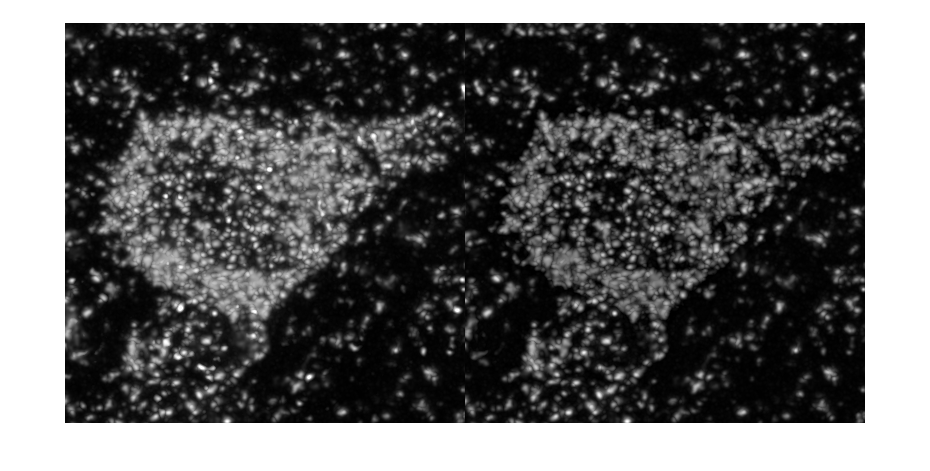


b_stack = im2double(b_stack);
b_stack = (b_stack - min(b_stack, [], 'all')) ./ (max(b_stack, [], 'all') - min(b_stack, [], 'all'));
b_stack = uint8(b_stack .* 255);

img_show_2d = max(input_img(:,:,:,1,1), [], 3);

img_show_b = max(b_stack, [], 3);
imshowpair(img_show_2d, img_show_b, 'montage')

se = strel('disk',6);
se_2 = strel('disk',2);
curr_slice = new_run.rawImages(:,:,1,1,1);
imshow(curr_slice)
marker = imerode(curr_slice, se);
imshow(marker)
obr = imreconstruct(marker, curr_slice);
imshow(obr)
curr_out = curr_slice - obr;
imshow(curr_out, [])
%mask = imbinarize(curr_out,0.06);
% mask = curr_out > 20;
% imshow(mask)
% curr_out(~mask) = 0;
% 
% bw = imopen(mask, se_2);
% imshow(bw)
% curr_out(~bw) = 0;
% imshow(curr_out, [])

curr_out = imsubtract(imadd(curr_out, imtophat(curr_out, se)), imbothat(curr_out, se));
imshow(curr_out)